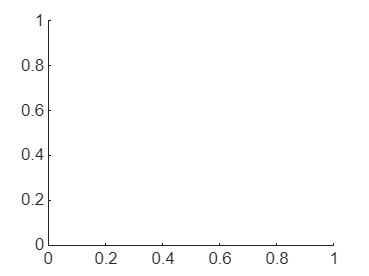

% file_speed_36="C:\Users\Abhijith_Kumble\Desktop\project_files\data_modified\motor_speed_36.csv";
% file_speed_30="C:\Users\Abhijith_Kumble\Desktop\project_files\data_modified\motor_speed_30.csv";
% file_speed_17_w_2="C:\Users\Abhijith_Kumble\Desktop\project_files\data_modified\motor_speed_17_weight_x_2.csv";
% file_speed_17_w="C:\Users\Abhijith_Kumble\Desktop\project_files\data_modified\motor_speed_17_weight.csv";
file_speed_17="C:\Users\Abhijith_Kumble\Desktop\project_files\data_modified\motor_speed_17.csv";

data=readtable(file_speed_17);
hold off;

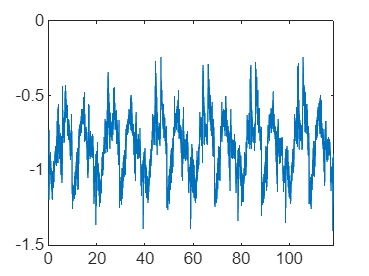

plot(data.Time_ms/1000, data.ax);shg

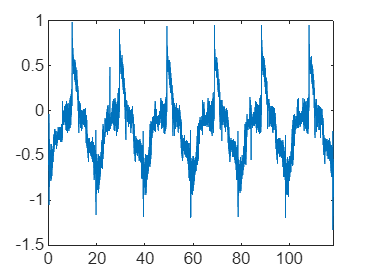

plot(data.Time_ms/1000, data.ay);shg

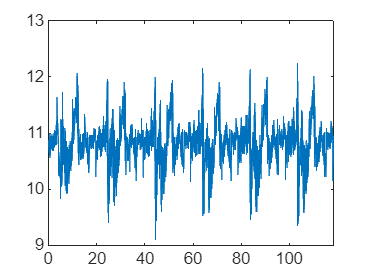

plot(data.Time_ms/1000, data.az);shg

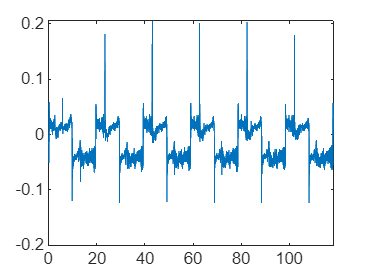

plot(data.Time_ms/1000, data.gx);shg

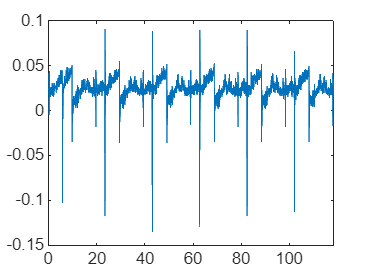

plot(data.Time_ms/1000, data.gy);shg

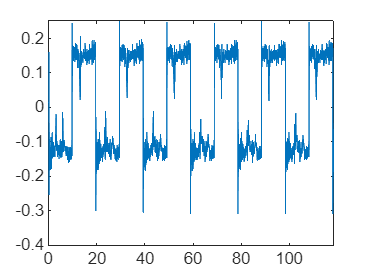

plot(data.Time_ms/1000, data.gz);shg

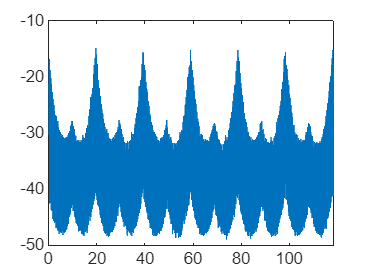

plot(data.Time_ms/1000, data.mx);shg

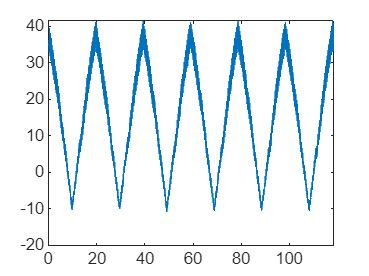

plot(data.Time_ms/1000, data.my);shg

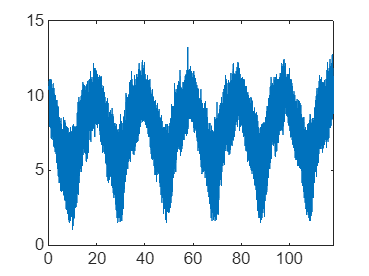

plot(data.Time_ms/1000, data.mz);shg

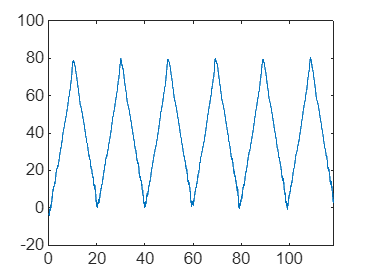

plot(data.Time_ms/1000, data.yaw);shg

time = data.Time_ms;
yaw_angle = data.yaw;

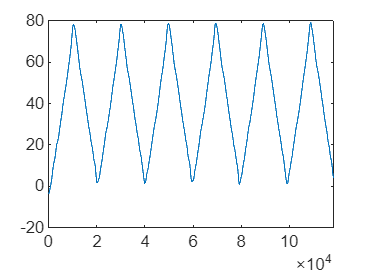

plot(time,smoothdata(yaw_angle, 'movmean', 30))

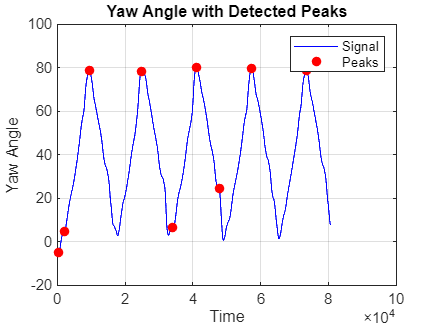

y=smoothdata(yaw_angle, 'sgolay', 45);
[peakVals, peakIdxs] = findpeaks(y);

% Plot original signal
plot(time, y, 'b'); 
hold on;

% Plot detected peaks on top of it
plot(time(peakIdxs), peakVals, 'ro', 'MarkerFaceColor', 'r');

hold off;
xlabel('Time');
ylabel('Yaw Angle');
title('Yaw Angle with Detected Peaks');
legend('Signal', 'Peaks');
grid on;

% breaks for 36 
breaks = [find(time == 1117), find(time == 17869), find(time == 32847), find(time==49036),find(time == 65352)]

breaks =           65        1021        1874        2796        3725



% breaks for 30
% breaks = [find(time == 59), find(time == 17362), find(time == 34249), find(time==51080),find(time == 68540), find(time==85355), find(time==102120)]

% breaks for 17
% breaks = [find(time == 775), find(time == 20163), find(time == 40079),find(time == 59396), find(time==79271),find(time == 99210)]

% breaks for 17_w
% breaks = [find(time == 796), find(time == 20077), find(time == 40079),find(time == 59439), find(time==79271),find(time == 99124)]

% breaks for 17_w_2
% breaks = [find(time == 796), find(time == 20077), find(time == 40079),find(time == 59396), find(time==79249),find(time == 99189)]

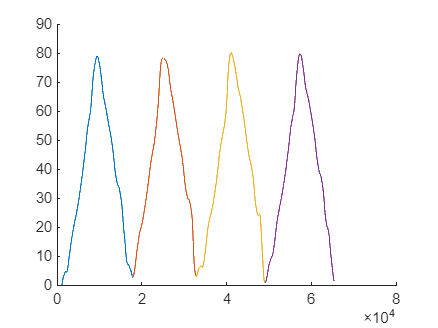

num_segments = length(breaks)-1;         % Number of segments , -1 if last cycle is not included
segments = cell(1, num_segments);      % Preallocate cell array

figure; hold on;
for i = 1:num_segments  % -1 if last cycle included
    idx_range = breaks(i):breaks(i+1)-1;
    seg = [time(idx_range), y(idx_range)];
    segments{i} = seg;
    plot(seg(:,1), seg(:,2));          % Plot time vs y
end

% Final segment %% comment out if not needed
% idx_range = breaks(end):length(y);
% seg = [time(idx_range), y(idx_range)];
% segments{num_segments} = seg;
% plot(seg(:,1), seg(:,2));
hold off;

N = 20500;  % Desired number of resampled points
num_segments = length(segments);
weight = 0;

resampled_with_duration = zeros(num_segments, N + 2);  % Preallocate

for i = 1:num_segments
    seg = segments{i};         
    t = seg(:,1);
    y = seg(:,2);

    duration = t(end) - t(1);  % Original time duration of the segment

    tq = linspace(t(1), t(end), N);  % Resample over actual time span
    yq = interp1(t, y, tq, 'linear');  % Interpolated signal

    resampled_with_duration(i, :) = [yq, weight, duration];  % Append duration as last column
end


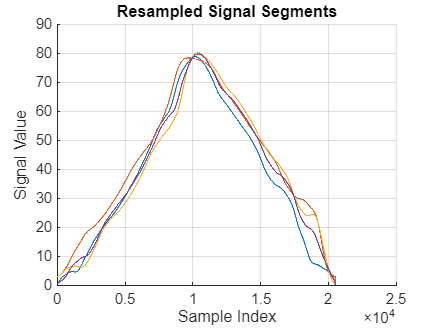

[num_segments, N] = size(resampled_with_duration);
N = N-1;
figure;
hold on;
for i = 1:num_segments
    plot(1:N, resampled_with_duration(i, 1:N));  % X-axis is sample index (1 to N)
end
hold off;

title('Resampled Signal Segments');
xlabel('Sample Index');
ylabel('Signal Value');
grid on;

T = array2table(resampled_with_duration);
writetable(T, ['C:\Users\Abhijith_Kumble\Desktop\project_files\resampled_data\with_weight_param\speed_36.csv']);